# MODELO ARX PRUEBA ESCALÓN

## IDENTIFICACION DE PROCESOS USANDO MINIMOS CUADRADOS

%Datos=xlsread('DATOSPULSO.xlsx');
%Datos(any(isnan(Datos), 2), :) = [];

%t=Datos(:,1);
%U=Datos(:,2);
%Y=Datos(:,3);

subplot(2,1,1)
plot(t,U,'* k','MarkerSize',4)
ylabel('Entrada')
grid on
subplot(2,1,2)
plot(t,Y,'o b','MarkerSize',4)
ylabel('Salida')
xlabel('Tiempo')
hold on
grid on

% Seleccionando na=3, nb=3, d=1
s=length(Y);

X=[-[0;Y(1:s-1)],-[0;0;Y(1:s-2)],-[0;0;0;Y(1:s-3)],[0;U(1:s-1)],[0;0;U(1:s-2)],[0;0;0;U(1:s-3)],[0;0;0;0;U(1:s-4)]];

%Matriz de covarianzas
Q=X'*X

Q =      2599200     2538000     2490300   -45209850   -44724750   -44161950   -43521450
     2538000     2526300     2465100   -44259600   -44104200   -43619100   -43056300
     2490300     2465100     2453400   -43309350   -43153950   -42998550   -42513450
   -45209850   -44259600   -43309350   841496600   828353575   815210550   802067525
   -44724750   -44104200   -43153950   828353575   824727575   811584550   798441525
   -44161950   -43619100   -42998550   815210550   811584550   807958550   794815525
   -43521450   -43056300   -42513450   802067525   798441525   794815525   791189525



%Vector de parámetros
Theta=inv(Q)*X'*Y

Theta =    -0.4488
   -0.4005
   -0.1083
    0.0268
   -0.0094
   -0.0019
   -0.0125



% Tu periodo de muestreo
T = 0.1;

z=tf('z',T);
Gpm = ((Theta(4)*z^3 + Theta(5)*z^2 + Theta(6)*z + Theta(7)) / (z^3 + Theta(1)*z^2 + Theta(2)*z + Theta(3))) * (z^(-1))

Gpm =
 
  0.02678 z^3 - 0.009375 z^2 - 0.001858 z - 0.01248
  -------------------------------------------------
      z^4 - 0.4488 z^3 - 0.4005 z^2 - 0.1083 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



%step(Gpm,'r--',2)
grid on
%Ym=step(Gpm,10  );
Ym = lsim(Gpm,U,t)

Ym =          0
   74.9912
   82.3981
  110.5540
   99.3345
  106.3776
  108.0932
  110.4694
  112.9854
  115.2520


plot(t,Ym)

%Validación del modelo
Sy=sum((Y-mean(Y)).^2)

Sy = 4.7902e+05

Sr=sum((Y-Ym).^2)

Sr = 1.3443e+05

R2=(Sy-Sr)/Sy

R2 = 0.7194

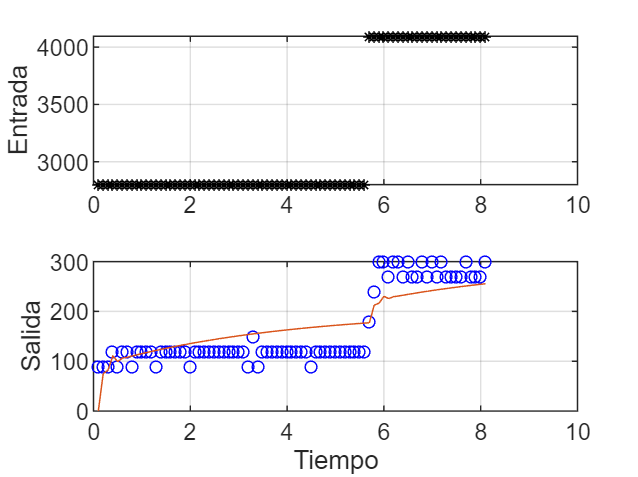

hold off

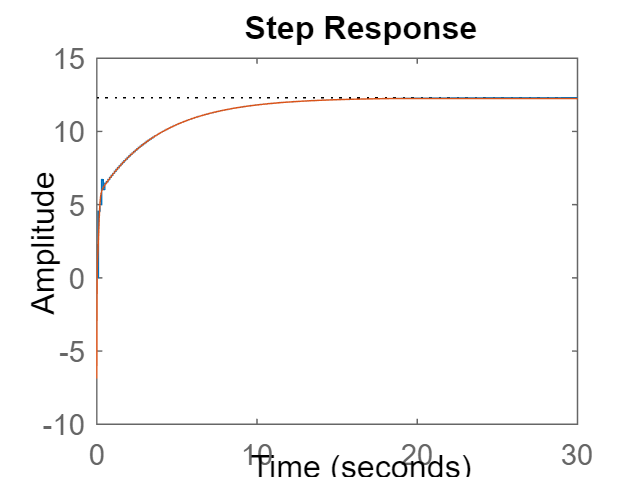



% Convertir Gpm_z a una función de transferencia en s usando la transformación bilineal
Gpm_s = d2c(Gpm, 'tustin'); 

% Ahora Gpm_s es tu función de transferencia en s
figure;
step(Gpm*170);
hold on
step(Gpm_s*170);